cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

load("../../results/trmse_raw.mat")

seq_starts = find(y_within.w_trial==1)+1

seq_starts =      2
    11
    20
    29
    38
    47


seq_stops = find(y_within.w_trial==9)+1

seq_stops =     10
    19
    28
    37
    46
    55


phi_between_arr = [];
for i=1:length(seq_starts)
seq = y_between(:,seq_starts(i):seq_stops(i));
phi_seq = seq{:,6:9};
phi_between_arr = [phi_between_arr, phi_seq];
end

p_between = [y_between(:,1), array2table(phi_between_arr)]

p_between = 14×25 table
    b_condition    phi_between_arr1    phi_between_arr2    phi_between_arr3    phi_between_arr4    phi_between_arr5    phi_between_arr6    phi_between_arr7    phi_between_arr8    phi_between_arr9    phi_between_arr10    phi_between_arr11    phi_between_arr12    phi_between_arr13    phi_between_arr14    phi_between_arr15    phi_between_arr16    phi_between_arr17    phi_between_arr18    phi_between_arr19    phi_between_arr20    phi_between_arr21    phi_between_arr22    phi_between_arr23    phi_between_arr24
    ___________    

p_within = y_within(any(y_within.w_trial==(1:4),2),["w_task", "w_gesture", "w_trial"])

p_within = 24×3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Human Learning"      "Co-Activation"         1   
    "Human Learning"      "Co-Activation"         2   
    "Human Learning"      "Co-Activation"         3   
    "Human Learning"      "Co-Activation"         4   
    "Human Learning"      "Differentiation"       1   
    "Human Learning"      "Differentiation"       

### Step 1. Visualize Raw Data in Panels

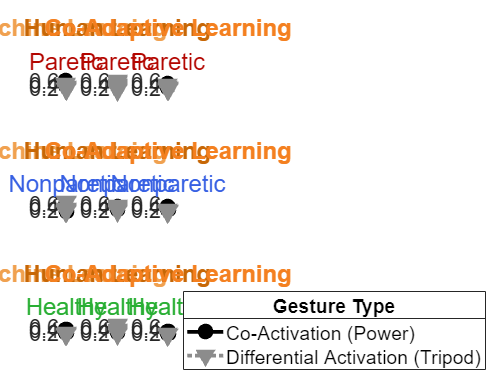

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
% tlo.Units = 'inches';
% tlo.OuterPosition = [0 0 17 10.5];
ax_handle_list = [];
for cond = ["par", "xpar", "hlt"]
    y_cond = p_between(p_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(p_within.w_task == task, p_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(p_within.w_task == task, p_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        plot(y_coact{:,:}', '-ok', 'MarkerFaceColor','k', 'LineWidth',3,'MarkerSize',10 )
        plot(y_diffact{:,:}', ':v', 'MarkerFaceColor',"#8c8c8c", 'LineWidth',3,'MarkerSize',10, 'Color',"#8c8c8c")
        hold off
        title(task)
        switch task
            case "Machine Learning"
                title(task, 'Color', "#f0a150")
            case "Human Learning"
                title(task, 'Color', "#c76706")
            case "Co-Adaptive Learning"
                title(task, 'Color', "#f48020")
        end
        switch cond
            case "par"
                subtitle("Paretic", 'Color', "#b30600")
            case "xpar"
                subtitle("Nonparetic", 'Color', "#3760e3")
            case "hlt"
                subtitle("Healthy", 'Color', "#29af34")
        end
        xticks(1:9)
        yticks(0:0.2:0.8)
    end
end
legend_handle = legend(["Co-Activation (Power)","", "", "", "Differential Activation (Tripod)"], "Location","eastoutside");
title(legend_handle, "Gesture Type")
linkaxes(ax_handle_list, 'xy')
ylim([min(phi_between_arr,[], 'all'), max(phi_between_arr,[], 'all')])
xlim([0 5])
% title(tlo, sprintf("%s Vs. Trial Count", upper(metric_type)))
set(ax_handle_list, 'FontSize', 18)

### Export to R

r_dataframe = [];
for i=1:height(p_between)
    if or(p_between{i,1} == "par", p_between{i,1} == "xpar")
        p_id = i+mod(i,2);
    else
        p_id = i;
    end
    p_tbl = array2table([p_between{i,2:end}', repmat(sprintf("p%02d",p_id), height(p_within),1), repmat(p_between{i,1}, height(p_within),1), p_within{:,:}], ...
        "VariableNames", ["rmse", "p_id", "p_cond", "task_type", "gesture_type", "trial_num"]);
    r_dataframe = [r_dataframe; p_tbl];
end

r_dataframe = convertvars(r_dataframe, ["rmse"], 'double');
r_dataframe = convertvars(r_dataframe, ["trial_num"], 'double');
r_dataframe = convertvars(r_dataframe, ["gesture_type", "task_type", "p_cond", "p_id"], 'categorical');
r_dataframe = r_dataframe(:,{'rmse' 'trial_num' 'gesture_type' 'task_type' 'p_cond', 'p_id'})

r_dataframe = 336×6 table
      rmse      trial_num     gesture_type         task_type        p_cond    p_id
    ________    _________    _______________    ________________    ______    ____

     0.45718        1        Co-Activation      Machine Learning     par      p02 
     0.39423        2        Co-Activation      Machine Learning     par      p02 
     0.38462        3        Co-Activation      Machine Learning     par      p02 
     0.34256        4        Co-Activation      Machine Learning     par      p02 
     0.17235        1        Differentiation    Machine Learning     par      p02 
     0.23068        2        Differentiation    Machine Learning     par      p02 
     0.14713        3        Differentiation    Machine Learning     par      p02 
     0.28512        4 

writetable(r_dataframe, '../../temp-data/rdf_rmse_phi_9.csv','WriteMode','overwrite')

### 2-Way ANOVA

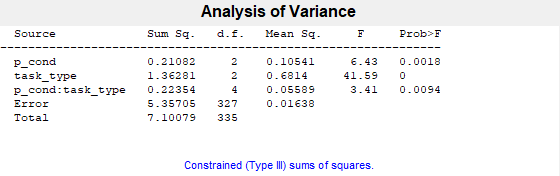

pvals =     0.0018
    0.0000
    0.0094


anova_tbl = 6×7 cell array
    {'Source'          }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'p_cond'          }    {[ 0.2108]}    {[   2]}    {[        0]}    {[  0.1054]}    {[  6.4344]}    {[    0.0018]}
    {'task_type'       }    {[ 1.3628]}    {[   2]}    {[        0]}    {[  0.6814]}    {[ 41.5936]}    {[8.0535e-17]}
    {'p_cond:task_type'}    {[ 0.2235]}    {[   4]}    {[        0]}    {[  0.0559]}    {[  3.4114]}    {[    0.0094]}
    {'Error'           }    {[ 5.3570]}    {[ 327]}    {[        0]}    {[  0.0164]}    {0×0 double}    {0×0 double  }
    {'Total'           }    {[ 7.1008]}    {[ 335]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
         source: 'anovan'
          resid: [336×1 double]
         coeffs: [16×1 double]
            Rtr: [9×9 double]
       rowbasis: [9×16 double]
            dfe: 327
            mse: 0.0164
    nullproject: [16×9 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {16×1 cell}
           vars: [16×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: [4×4 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms =      1     0
     0     1
     1     1


[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}}, ...
    'varnames',["p_cond", "task_type"], ...
    'model',2)

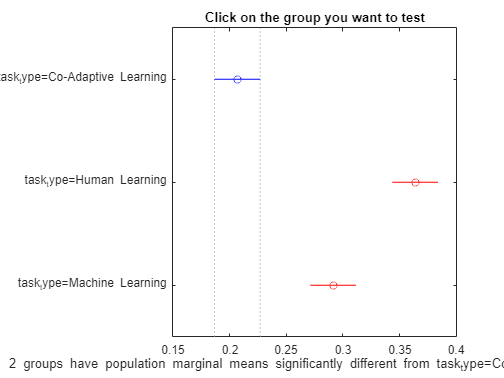

ans =     1.0000    2.0000   -0.1970   -0.1567   -0.1164    0.0000
    1.0000    3.0000   -0.1247   -0.0844   -0.0441    0.0000
    2.0000    3.0000    0.0320    0.0723    0.1126    0.0001


figure
multcompare(stats, "Dimension",[2])